addpath('Classes')
addpath('Simulink Models')
addpath('Functions')

%Make sure symprefs are set correctly for this script
sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput', false);
sympref('FloatingPoint',true);
sympref('TypesetOutput',true);

# Test and Optimize Linear Moving Setpoint Controller with Feed-Forward

%Create a variable definitions object if one does not already exist. 
if (~exist('VDefs', 'var')) 

    VDefs = Var_Defs;  %Create an object of the class Var_Defs

end 

%Create a u-joint Kinematics object if one does not already exist. 
if (~exist('UJ_Knmtcs', 'var')) 

    UJ_Knmtcs = UJ_Knmtcs(VDefs); %Create an object of the class UJ_Knmtcs
    UJ_Knmtcs.derive_all; %Run all of its derivation functions

end 

%Create a ball-plate kinematics object if one does not already exist. 
if (~exist('BP_Knmtcs', 'var')) 

    BP_Knmtcs = BP_Knmtcs(VDefs, UJ_Knmtcs); %Create an object of the class BP_Knmtcs
    BP_Knmtcs.Derive_Both; %Derive all the kinematic equations for the ball-plate system
end 

%Create a ball-plate kinetics object if one does not already exist. 
if (~exist('BP_Kinetics', 'var')) 

    BP_Kinetics = BP_Kinetics(VDefs, UJ_Knmtcs, BP_Knmtcs); %Create an object of the class BP_Kinetics
    BP_Kinetics.Derive_NL_EOMs; %Derive the nonlinear equations of motion for the ball-plate system
    BP_Kinetics.Num_Params_n_Assumptions; %Input numerical parameters and assumptions

end 


%Create a linearized EOMs object if one does not already exist. 
if (~exist('Lnrzed_EOMs', 'var')) 

    Lnrzed_EOMs = Lnrzed_EOMs(VDefs, BP_Kinetics); %Create an object of the class Lnrzed_EOMs
    Lnrzed_EOMs.Derive_8th_Ordr_Lin_Sys;
    Lnrzed_EOMs.Derive_4th_Ordr_Lin_Sys;
end 

%Create a nonlinear decoupled EOMs object if one does not already exist. 
if (~exist('NL_Dcpld_EOMs', 'var')) 

    NL_Dcpld_EOMs = NL_Dcpld_EOMs(VDefs, BP_Kinetics); %Create an object of the class NL_Dcpld_EOMs
    NL_Dcpld_EOMs.Num_Params;

end

plant_model = rhs(BP_Kinetics.NL_NumEOMs); %Choose the coupled nonlinear model as the plant. Torques still approximated

if (~exist('LMSPC_FF', 'var'))

    LMSPC_FF = Lin_Mvng_Stpt_Cntr_SS(Lnrzed_EOMs, plant_model, VDefs, 'SS PID FF Controller');

end

## Moving Setpoint 

Desired Analytical Trajectories in x and y

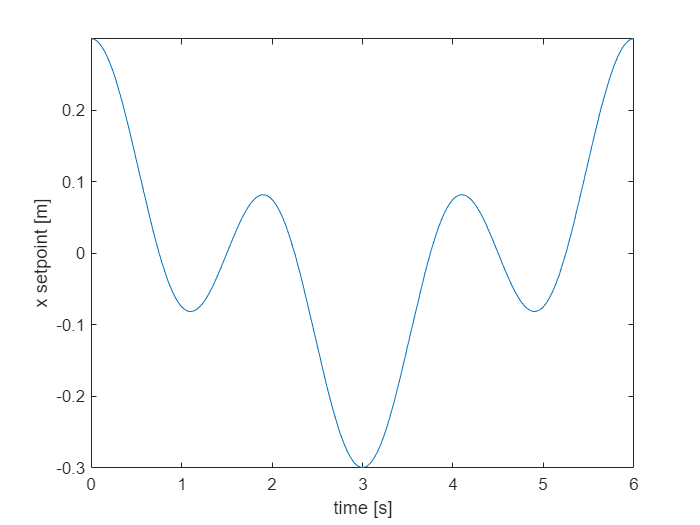

%Ideal trajectory parameters
r_sim = .3; % radius of trajectory [m] Touch screen is about 30 cm wide
% freq = 1/9; %rotations per second: 1/9 for octofolium is about as fast as it gets
% freq = 1/6; %rotations per second:  1/6 for quadrifolium is about as fast as it gets
freq = 1/6;
omega_sim =  2*pi*freq; %angular frequency of circular trajectory 

%Ideal trajectory symfuns
%Figure 8
% des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
% des_traj_sym_y(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);

%Circle
% des_traj_sym_x(VDefs.t) = r_sim*sin(omega_sim*VDefs.t);
% des_traj_sym_y(VDefs.t) = r_sim*cos(omega_sim*VDefs.t);

%Simple STAY AT THE ICs SETPOINT for tuning inner angular loops
% des_traj_sym_x(VDefs.t) = x_0(1) + 0*VDefs.t;
% des_traj_sym_y(VDefs.t) = x_0(5) + 0*VDefs.t;

%Rose curve specified by k
n = 2;
d = 1;
k = n/d;
des_traj_sym_x(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*cos(omega_sim*VDefs.t);
des_traj_sym_y(VDefs.t) = r_sim*cos(k*omega_sim*VDefs.t)*cos(omega_sim*VDefs.t + pi/2);

figure
fplot(des_traj_sym_x) 
xlim([0 2*pi/omega_sim]); 
ylabel('x setpoint [m]')
xlabel('time [s]')

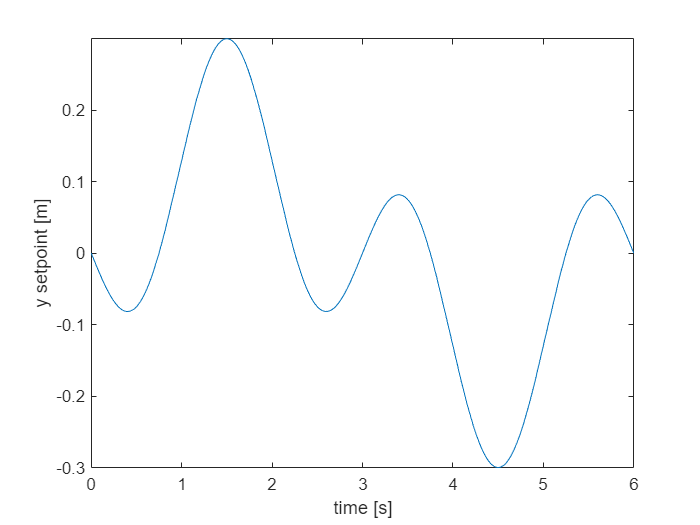


figure
fplot(des_traj_sym_y) 
xlim([0 2*pi/omega_sim]); 
ylabel('y setpoint [m]')
xlabel('time [s]')

## Gain Matrices 

A1a = LMSPC_FF.sys_mats.A1a;
A2a = LMSPC_FF.sys_mats.A2a;

B1a = LMSPC_FF.sys_mats.B1a;
B2a = LMSPC_FF.sys_mats.B2a;

Q_e_ix = 1/15^2;
Q_e_x = 1/.001^2;
Q_e_xd = 1/.002^2; 
Q_b = 1/deg2rad(40)^2/.5; 
Q_bd = 1/omega_sim^2/3;


Q = [Q_e_ix 0 0 0 0; 
     0 Q_e_x 0 0 0;
     0 0 Q_e_xd 0 0;
     0 0 0 Q_b 0;
     0 0 0 0 Q_bd];

R = 1/(73/1000)^2/10; 

K1 = lqr(double(A1a_FF), double(B1a_FF), Q,R)

K1 =    -0.0154 -233.0711 -175.5057 -268.7115  -34.2993


K2 = lqr(double(A2a_FF), double(B2a_FF), Q,R)

K2 =     0.0154  233.0711  175.5057 -268.7115  -34.2993


## Simulate the Feed-Forward Controller

%Specify simulation time
tspan = [0 2*pi/omega_sim]*3;

%Specify initial conditions and compute initial outputs
x_0 = 1/2*[r_sim; 0; 0; 0; r_sim; 0; 0; 0];

%First order smoothing with time constant Tau
Tau = 2; 

LMSPC_FF.Run_Sim(des_traj_sym_x, des_traj_sym_x, tspan, x_0,Tau, K_FF1, K_FF2);

simout_FF = LMSPC_FF.sim_response

simout_FF =   Simulink.SimulationOutput:

                   tout: [41727x1 double] 
                      u: [41727x2 double] 
                      x: [41727x8 double] 
                x_s_vec: [41727x4 double] 
                y_s_vec: [41727x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


## Plot the Respose

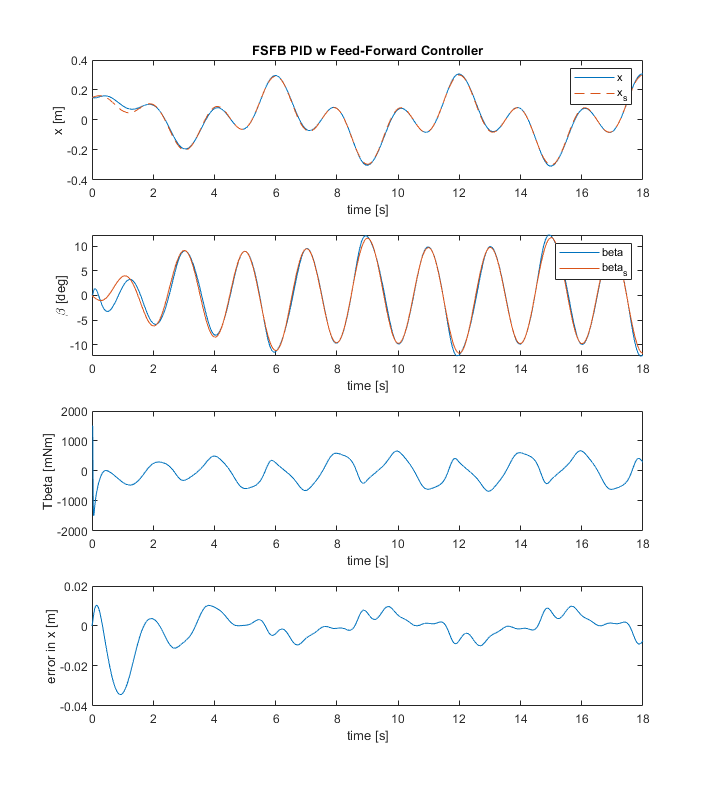

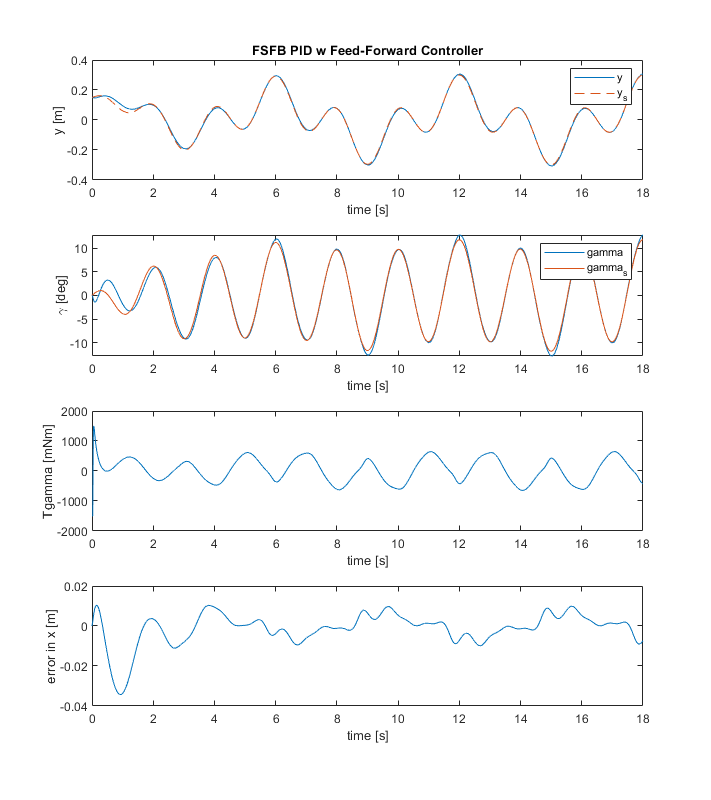

%Plot the FF controller results
FF_fig = LMSPC_FF.plot_results('FSFB PID w Feed-Forward Controller');